clc;
clear;
syms x

AE  = 1

AE = 1

% Domain of X
x0 = 0;
xL = 1;
L = xL; % Length

**Differential Equations**


$$a\frac{d^2 u}{dx^2 }+b\frac{du}{dx}+c{\left(x\right)}u=f{\left(x\right)}$$


a = AE;
% In spring case for a =1 only it is working, for plotting exact solution
b = 0;
c =0;
f =x;

**Order of Interpolation Function & No of Elements**

P = 1; % Only works till P = 6  % Gauss points restriction
% P Order of Interpolation Function for element
ndofel = P+1;
% No of elements
e = 1;

**Boundary Values**

% Get the handle of the command window
commandwindow;
% Prompt the user to input boundary conditions at x0
prompt_x0 = 'Enter the type of boundary condition at x0 (1. Dirichlet, 2. Neumann, 3. Spring): ';
type_x0 = input(prompt_x0);

switch type_x0
    case 1
        u0 = input('Enter the Dirichlet value u at x0: ');
    case 2
        Q0 = input('Enter the Neumann value (du/dx) at x0: ');
    case 3
        K0 = input('Enter the spring constant K at x0: ');
        Del0 = input('Enter the spring displacement Del at x0: ');
    otherwise
        error('Invalid boundary condition type at x0');
end


% Prompt the user to input boundary conditions at xL
prompt_xL = 'Enter the type of boundary condition at xL (1. Dirichlet, 2. Neumann, 3. Spring): ';
type_xL = input(prompt_xL);

switch type_xL
    case 1
        uL = input('Enter the Dirichlet value u at xL: ');
    case 2
        P1 = input('Enter the Neumann value (du/dx) at xL: ');
    case 3
        K1 = input('Enter the spring constant K at xL: ');
        Del1 = input('Enter the spring displacement Del at xL: ');
    otherwise
        error('Invalid boundary condition type at xL');
end

% Prompt the user to input information about a point load
prompt_pointLoad = 'Is there a point load present? (1.yes, 2.no): ';
pointLoadResponse = input(prompt_pointLoad); % Numeric input

switch pointLoadResponse
    case 1
        PL1 = input('Enter the value of the point load: ');
        PL1_loc = input('Enter the Point Load Location: ');
    case 2
        disp('No point load present, continuing with the rest of the code.');
    otherwise
        error('Invalid response for the presence of a point load. Please enter 1.yes or 2.no.');
end

No point load present, continuing with the rest of the code.



%Continue with the remaining code...

if exist('PL1_loc', 'var') && exist('PL1', 'var')
    F_location = PL1_loc;  
    x_vector = GlobalLocation(x0, xL, P, e);
    
    [incremented_e, decremented_e, valuePL] = adjust_e(x_vector, P, x0, xL, F_location, e);
     if valuePL == 1

        % Continue with the rest of the code as usual if valuePL is 1.
        adjusted_e = choose_e(incremented_e, decremented_e, e);
        x_vector1 = GlobalLocation(x0, xL, P, adjusted_e);
        PL1_index = find_indices(x_vector1, F_location);
        disp(['Indices where x_vector == F_location: ', num2str(PL1_index)]);

    elseif valuePL == 2
       
        prompt_adjust = ['For given Point load location and element number Their is No nodal point to keep Point load' ...
            ' Do you want to adjust the element value? (1.yes, 2.no): '];
        adjustResponse = input(prompt_adjust);
        
        if adjustResponse == 1
            adjusted_e = choose_e(incremented_e, decremented_e, e);
            disp(['Adjusted New elements is: ', num2str(adjusted_e)]);
            x_vector1 = GlobalLocation(x0, xL, P, adjusted_e);
            PL1_index = find_indices(x_vector1, F_location);
            disp(['Indices where x_vector == F_location: ', num2str(PL1_index)]);

        elseif adjustResponse == 2

            disp('Exiting the program.');
            return; % This will exit the script

        else
            error('Invalid response. Please enter 1 for yes or 2 for no.');
        end
    else
        error('Unexpected valuePL. Expected values are 1 or 2.');
     end
end


if exist('adjusted_e', 'var')
    e = adjusted_e;
end

**FEM Solver**

[K_global_D_bc, Fv, S, X_nodes] = FEM_Processor(P, e, L, a, b, c, f);

Gv = sym(zeros(S, 1));
Sv = sym(zeros(S, 1));

if exist('PL1_index', 'var') && exist('PL1_loc', 'var') && exist('PL1', 'var')
    Gv(PL1_index) = PL1
end

% For X0 left node we need to add correction factor
if exist('Q0', 'var') 
    Q0 = AE *Q0
    Gv(1) = -Q0;   % Correction factor Added
end

if exist('K0', 'var') && exist('Del0', 'var')
    Sv(1) = -K0 * Del0;    % Correction factor Added
    K_global_D_bc(1, 1) = K_global_D_bc(1, 1) + K0;
end

if exist('P1', 'var') 
    P1 = AE *P1
    Gv(end) = P1;
end

P1 = 0.0100


if exist('K1', 'var') && exist('Del1', 'var')
    Sv(end) = K1 * Del1;  
    K_global_D_bc(end, end) = K_global_D_bc(end, end) + K1;
end

Gv = Gv *a;

RHS = Fv + Gv + Sv;

% Handle boundary conditions at x0
if exist('u0', 'var') 
    K_global_D_bc(1, :) = [1, zeros(1, S-1)];  % u0 = 0
    RHS(1) = u0;  % RHS of equation
end

% Handle boundary conditions at xL
if exist('uL', 'var') 
    K_global_D_bc(end, :) = [zeros(1, S-1), 1];  % uL = 0
    RHS(end) = uL;  % RHS of equation
end  

K_global_D_bc;
RHS;

u_nodes = double(K_global_D_bc \ RHS);% u at nodal points
% disp("-------------------------------------------------------------")
% myTable = table(X_nodes, u_nodes, 'VariableNames', {'Nodal Location', 'u node value'});
% disp(myTable);
% disp("-------------------------------------------------------------")

syms x  u_e(x)
%----------------------------------------------------------------------------
deqn = a*diff(u_e,x,2)+b*diff(u_e,x,1)+c*u_e == f;

d_ue(x)= diff(u_e,x);


if exist('Q0', 'var') 
    ic0=d_ue(x0) == Q0;  

elseif exist('K0', 'var') && exist('Del0', 'var')
    ic0=d_ue(x0) == K0 * (Del0+u_nodes(1));    
else
    ic0=u_e(x0) == u0;
end

if exist('P1', 'var') 
    icL=d_ue(xL) == P1;  

elseif exist('K1', 'var') && exist('Del1', 'var')
    icL=d_ue(xL) == K1 * (Del1-u_nodes(end));    
else
    icL=u_e(xL) == uL;
end

u_exact = dsolve(deqn,[ic0 icL]);
u_exact_equation = u_exact

$$u\_exact\_equation = \frac{x^{3}}{6}-\frac{49\,x}{100}$$

%----------------------------------------------------------------------------------
clear u_e(x)

These are the Functions are useful for point load, and adjusting the element number according to point load location 

- lagrange_interpolation

- choose_e

- find_indices

- adjust_e

- uprime

[element_numbers,interpolating_functions,ranges,u_prime_values] = uprime(u_nodes,X_nodes,P,e,S);

% Create and display the table
Table1 = table(element_numbers, interpolating_functions, ranges, ...
          'VariableNames', {'Element Number', 'Interpolating Function', 'Range'});
disp(Table1);

    Element Number    Interpolating Function      Range   
    ______________    ______________________    __________

          1              {'-(97*x)/300'}        {'[0, 1]'}



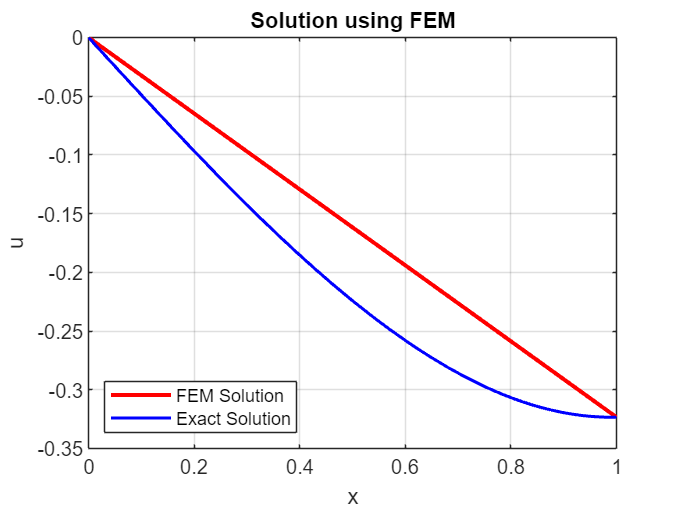



% myTable1 = table(X_nodes, u_nodes,u_prime_values', 'VariableNames', {'Nodal Location', 'u node value','du/dx'});
% disp(myTable1);
% disp("-------------------------------------------------------------")

%Plot the FDM Solution and the actual solution
figure;
plot(X_nodes, u_nodes, "r", "LineWidth", 2, "DisplayName", "FEM Solution"); 
hold on;
fplot(x, u_exact_equation,[x0 xL] ,"b", "LineWidth", 1.5, "DisplayName", "Exact Solution");
xlabel("x");
ylabel("u");
title("Solution using FEM");
legend('Location', 'southwest');
grid on;


du_exact_equation = diff(u_exact_equation,x)

$$du\_exact\_equation = \frac{x^{2}}{2}-\frac{49}{100}$$

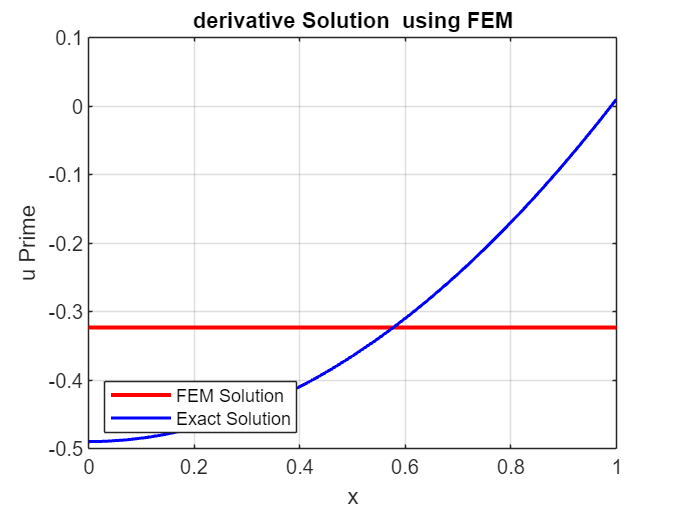


%Plot the FDM Solution and the actual solution
figure;
plot(X_nodes, u_prime_values, "r", "LineWidth", 2, "DisplayName", "FEM Solution"); 
hold on;
fplot(x, du_exact_equation,[x0 xL] ,"b", "LineWidth", 1.5, "DisplayName", "Exact Solution");
xlabel("x");
ylabel("u Prime");
title("derivative Solution  using FEM");
legend('Location', 'southwest');
grid on;


% sigmaXXAtNodes = E11 * u_prime_values';
% 
% myTable1 = table(X_nodes, u_nodes,u_prime_values',sigmaXXAtNodes, 'VariableNames', {'Nodal Location', 'u node value','du/dx', 'sigma xx'});
% disp(myTable1);
% disp("-------------------------------------------------------------")
% 
% % Find the absolute maximum value
% [sigmaXXMaxValue, index] = max(abs(sigmaXXAtNodes));
% 
% % Actual maximum value based on absolute
% sigmaXYZMaxLOCATION = X_nodes(index);
% 
% % Display results
% disp(['sigma XX Max Value: ', num2str(sigmaXXMaxValue),'MPa']);
% disp(['sigma XXMax LOCATION ', num2str(sigmaXYZMaxLOCATION),' mm']);
% 


